%%

clear all
G = 1.4;
R=8.314/29

R = 0.2867

alpha =5;%[0 5 10]
Mos1_target = 2.650;
Ma_range = 2:0.001:4;
% Ma_range = 2.0:0.001:2.9;
%for AOA=1:length(alpha)
Sigs = 15:0.01:45;
results5 = [];
A0bAc=[];
t=14;
flag = true;
Po2bPoa = [];
for Ma = Ma_range
    rhs = [];
    for sig = Sigs
        temp = (2 * (1 + ((G-1)/2) * Ma^2 * (sind(sig))^2) / ((G+1) * Ma^2 * sind(sig) * cosd(sig))) / tand(sig-alpha);
        rhs = [rhs temp];
    end
    threshold = abs(rhs - 1);
    [~, I] = min(threshold);
    finalSig1 = Sigs(I);
    Man = Ma * sind(finalSig1);
    Mos1n = sqrt((Man^2 + 2/(G-1)) / ((2*G/(G-1)) * Man^2 - 1));
    Mos1 = Mos1n / sind(finalSig1-alpha);
    results5 = [results5; Ma, Mos1];
    if flag == true && abs(Mos1 - Mos1_target) < 1e-3
        M_design_effective = Ma;
        fprintf("For alpha = %d, Ma = %.2f produces Mosa = %.2f\n", alpha, M_design_effective, Mos1)
        flag = false;
    end

    del=3.5;
    rhs=[];
    lhs=1;
    for sig=Sigs
        temp=(2*(1+((G-1)/2)*Mos1^2*(sind(sig))^2)/((G+1)*Mos1^2*sind(sig)*cosd(sig)))/tand(sig-del);
        
        rhs=[rhs temp];
    end
    threshold=abs(rhs-lhs);
    [~,I]=min(threshold);
    
    finalSig2=Sigs(I);
    
    Mos1n_in=Mos1*sind(finalSig2);
    Mos2n=sqrt((Mos1n_in^2 + 2/(G-1))/((2*G/(G-1))*Mos1n_in^2 - 1 ));
    
    Mos2=Mos2n/sind(finalSig2-del);
   
    
    %%Part 2
%     M1=-100;
    Gmos=((G+1)/(G-1))^0.5*atan((((G-1)/(G+1))*(Mos1^2-1))^0.5)-atan((Mos1^2-1)^0.5);
    theta=15;
    Gm1 = Gmos - (theta*3.14)/180;
    rhs=[];
    lhs=Gm1;
    M1_range=[0:0.001:4];
    for M=0:0.001:4
        temp=((G+1)/(G-1))^0.5*atan((((G-1)/(G+1))*(M^2-1))^0.5)-atan((M^2-1) ^ 0.5);
        
        rhs=[rhs temp];
    end
   
    
    threshold=abs(rhs-lhs);
    [~,I]=min(threshold);
    
    M1=M1_range(I);
  if Mos1<=Mos1_target
      Po1bPoOS1=(((((G+1)/2)*(Mos1n_in^2))/(1+(((G-1)/2)*(Mos1n_in^2))))^(G/(G-1)))/((((2*G)/(G+1))*(Mos1n_in^2))-((G-1)/(G+1)))^(1/(G-1));%Poy/PoO
      PoOS1bPoa=(((((G+1)/2)*(Man^2))/(1+(((G-1)/2)*(Man^2))))^(G/(G-1)))/((((2*G)/(G+1))*(Man^2))-((G-1)/(G+1)))^(1/(G-1));%Poy/PoO
      Po1pbPo1=(((((G+1)/2)*(M1^2))/(1+(((G-1)/2)*(M1^2))))^(G/(G-1)))/((((2*G)/(G+1))*(M1^2))-((G-1)/(G+1)))^(1/(G-1));%Poy/PoO
      temp=Po1bPoOS1 * PoOS1bPoa * 0.95 * Po1pbPo1;
      Po2bPoa= [Po2bPoa temp];
      PbPom1=(1+((G-1)/2)*M1^2)^-(G/(G-1))*((G/R)^0.5*M1*(1+((G-1)/2)*M1^2)^0.5);
      PbPoma=(1+(G-1)/2*Ma^2)^-(G/(G-1))*((G/R)^0.5*Ma*(1+((G-1)/2)*Ma^2)^0.5);
      tt=(Po1bPoOS1*PoOS1bPoa)*(PbPom1/PbPoma)*(0.519);
      A0bAc=[A0bAc tt];
  else
      Mdpo2bpoa = Po2bPoa(find(Ma_range==M_design_effective));
      temp=Mdpo2bpoa*exp(0.96*(M_design_effective-Ma));% b=0.96 l/h=4
      Po2bPoa= [Po2bPoa temp];
     if finalSig1>alpha+14
         tt=nan;
         A0bAc=[A0bAc tt];
     
     else
          tt=sind(t+alpha)/sind(t);
      A0bAc=[A0bAc tt];
     end
  end
end

For alpha = 5, Ma = 2.89 produces Mosa = 2.65


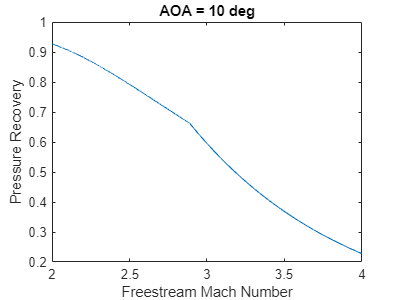


plot(Ma_range,Po2bPoa)
title('AOA = 10 deg')
xlabel('Freestream Mach Number')
ylabel('Pressure Recovery')

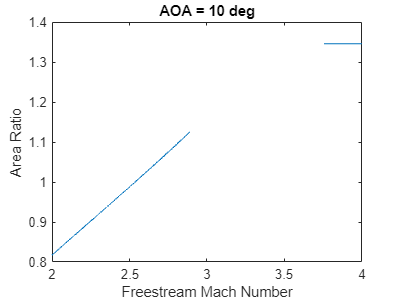


figure
plot(Ma_range,A0bAc)
title('AOA = 10 deg')
xlabel('Freestream Mach Number')
ylabel('Area Ratio')
hold on
plot([Ma_range(1179),Ma_range(1579)],[A0bAc(1179),A0bAc(1579)])